## Cepstral 26 Features - Cubic SVM - Model Optimizer

This script optimizes the accuracy performance of a Cubic SVM classification model for the modified Cepstral 26 features feature set. The optimization of this model is done through the built in hyperparameter optimizer.

See the following links for more details about Support Vector Machines (SVM) in Matlab:

    [https://www.mathworks.com/help/stats/support-vector-machines-for-binary-classification.html](https://www.mathworks.com/help/stats/support-vector-machines-for-binary-classification.html)

    [https://www.mathworks.com/help/stats/fitcsvm.html](https://www.mathworks.com/help/stats/fitcsvm.html) 

#### Script Setup

% Load pre-generated feature set
load('E:\UW\Project\EnvNoiseDetector\data\Features\FeaturesSNR6Cepstral26features.mat')

% Find base directory
basedir = fileparts(pwd);

% Set data directory
datadir = fullfile(basedir,"data","DataExamplesv2");

% File name for Monte Carlo results
mcfolder = fullfile(basedir,"data","Models");
mcfileName = "Cepstral26CubicSvmSim";
csvfileName = "Cepstral26CubicSvmSim.csv";

#### Data Setup

% Subset signal and contamination sets
rng(42);
fileDescripts = readtable(fullfile(datadir,"FileDescriptions.xlsx"),'TextType','string');
fileDescripts.AircraftPresent = fileDescripts.AircraftPresent == "Y";
fileDescripts.Contaminated = fileDescripts.Contaminated == "Y";

contaminationFiles = fileDescripts.FileName(fileDescripts.Contaminated);
signalFiles = fileDescripts.FileName(~fileDescripts.Contaminated);

#### Bayesian Optimizer

Copying objective function to workers...
Done copying objective function to workers.


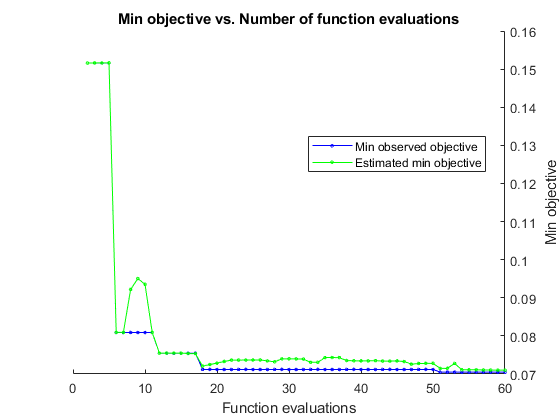

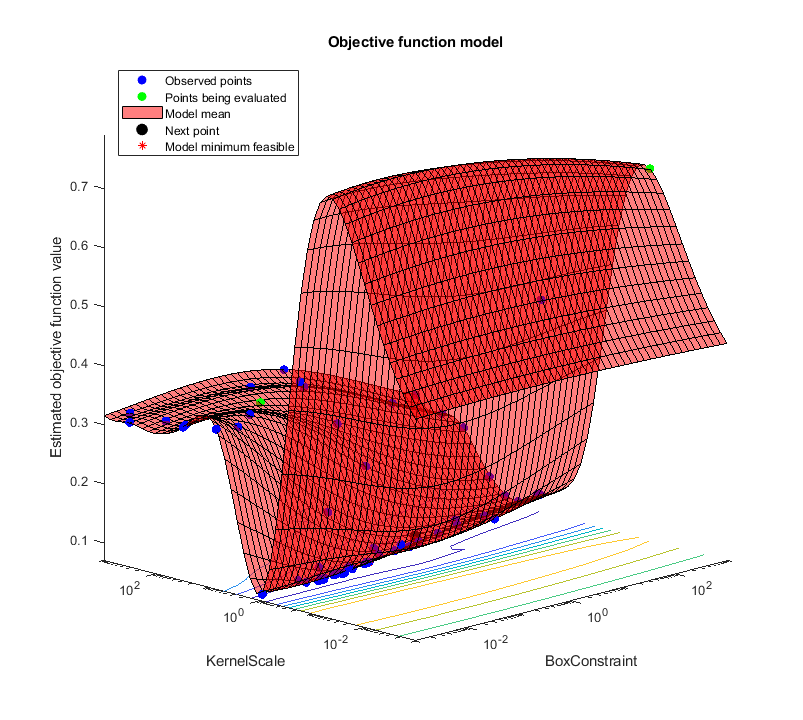

|===============================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |              |
|===============================================================================================================|
|    1 |       4 | Error  |         NaN |     0.41095 |         NaN |         NaN |     0.089695 |    0.0016786 |
|    2 |       4 | Accept |     0.15161 |      1.3091 |         NaN |     0.15161 |      0.14805 |       7.2332 |
|    3 |       3 | Accept |     0.31457 |      1.5875 |     0.15161 |     0.15162 |    0.0023262 |       732.21 |
|    4 |       3 | Accept |     0.25071 |      1.1279 |     0.15161 |     0.15162 |       2.3393 |       75.182 |
|    5 |       3 | Error  |         NaN |     0.28724 |     0.15161 |     0.15162 |     

% Train a cubic SVM classifier
% Setup a cross-validation partition
c = cvpartition(size(xfeatures, 1),'KFold',10);
useparpool = ~isempty(gcp);

% Setup the Bayesian optimizer
opts = struct('Optimizer','bayesopt','ShowPlots',true,'CVPartition',c,...
    'AcquisitionFunctionName','expected-improvement-plus','Verbose',2);
svmmod = fitcsvm( ...
            xfeatures(:,1:26), ...
            xfeatures(:,27), ...
            'KernelFunction','polynomial', ...
            'PolynomialOrder', 3, ...
            'Standardize', true, ...
            'OptimizeHyperparameters','auto', ...
            'HyperparameterOptimizationOptions',struct('UseParallel',useparpool,'MaxObjectiveEvaluations',60,'KFold',5));

#### Evaluate Model

The ideal settings the Bayesian optimizer found for BoxConstraint and KernelScale were 0.31037 and 2.4063 respectively.

% Evaluate model performance on test data
rng(98)
[mdlCepstral26CubicSvm, modelAccuracy, validationPredictions] = trainCubicSvmClassifier(xfeatures,2.4063,0.31037);
[acc,fpr,fnr,f1] = scoreModel(table2array(xfeatures(:,27))==1, validationPredictions==1);
display(['Model Accuracy: ',num2str(acc, 4)]);

Model Accuracy: 0.9312


display(['Model F1 Score: ',num2str(f1, 4)]);

Model F1 Score: 0.9299


display(['Model False Positive Rate: ',num2str(fpr, 4)]);

Model False Positive Rate: 0.05109


display(['Model False Negative Rate: ',num2str(fnr, 4)]);

Model False Negative Rate: 0.08657
